# Title

Bertrand Aristide Inshuti, Derek Martielli

I'm looking at the project 1 final submission assignment for guidance. Also looking at the rubric for project 2 final submission.

## Question

###     How does limiting the size of social gatherings affect the rate of disease spread in a population? 

        This question is more general as we are aiming to find trends instead of specific values. The question is also more rhetorical as we are not in direct control of limiting the sizes of social gatherings. The motivation for this question comes from the experience of COVID-19. During the peak of the virus many governments set limits on sizes for social gatherings. While this was far from the only measure implemented, it would be interesting to see how it may have helped lessen the spread.

#### Research Synthesis Matrix

      A lot of the research we found assumed a distribution of group sizes and looked at the impact of each group size. While this doesn't answer our question it does give guidance on how we might make and validate our model. We found that the use of extra parameters beyond SIR was not necessary, and that we can expect lower person mobility to reduce disease spread.

## **        Methodology/Model**

        To investigate how the limiting size of social gatherings limits the spread of disease, we built an agent-based SIR model(ABSIR) simulating disease transmission in a population of 200 individuals over 90 time steps. Each agent could be susceptible, infected, or recovered, and the model incorporated both person-to-person interactions and structured “pods,” which represent social interactions of fixed sizes. Infection and recovery probabilities were set at 0.4 and 0.1, respectively, and agents had a 60% chance of participating in a gathering at each time step. We initialized the population with approximately 10% infected individuals and ran the simulation to track how many people were infected at every timestep. 

        To analyze how gathering size influences spread, we performed a parameter sweep varying pod sizes from 2 to 10. For each pod size, we re-ran the model and recorded the total number of infected individuals over time. Comparing these infection curves showed that larger gatherings amplify transmission, while smaller pods slow the epidemic. This approach enabled a controlled, systematic evaluation of how social-group size constraints shape outbreak dynamics.

## Result

        In all simulations we ran, we observed that larger gatherings led to significantly higher, faster infection peaks, while smaller pods had lower, slower infection peaks. When the pods were smaller, like 2-4 people, the infection curve rose gradually and peaked at a much lower level, showing that limiting gatherings effectively suppressed transmission. As pod sizes increased to 6-10 people, infections grew rapidly, producing earlier and much higher peaks. The sweep demonstrated that gathering size is the main amplifier of disease spread, with even moderate increases in group size causing substantial increases in total infections over time.

## **Interpretation: Test**

    stuff

## AI Statement:

    AI was not used during this project.

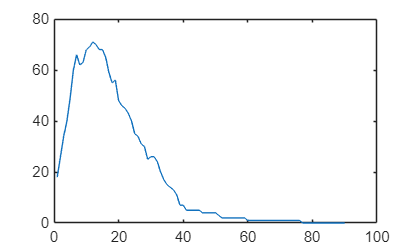

%Demo Model
n_population = 200;
pod_size = 4;
T = 90;
infection_rate = 0.4;
recovery_rate = 0.1;
gathering_chance = 0.6;
Iv0 = rand(n_population,1)<0.1;
[~,Ih,Ir] = simulate_absir(n_population,Iv0, T, infection_rate, recovery_rate,pod_size,gathering_chance);
I_count = sum(Ih, 1);
plot(I_count);

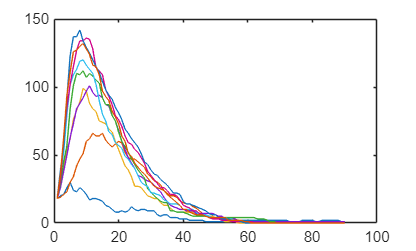



%Demo Sweep
I_count_sweep = [];
for i=2:10
    [~,Ih,~] = simulate_absir(n_population,Iv0, T, infection_rate, recovery_rate,i,gathering_chance);
    I_count_sweep(:,i-1) = sum(Ih, 1).';
end
plot(I_count_sweep)